Let's start by creating some data on which to perform inference.

rng(14);
n=50;
rand1 = normrnd(0.3,0.1,[1,floor(n/3)]);
rand3 = gamrnd(.5,0.5,[1,floor(n/3)]);
rand4 = normrnd(0.7,0.01,[1,ceil(n/3)]);

y = ([rand1,rand3,rand4])

y =     0.3073    0.4000    0.3968    0.2122    0.2618    0.3954    0.3032    0.2525    0.3126    0.1953    0.3979    0.2654    0.3232    0.2119    0.3361    0.2314    0.1291    0.2038    0.2110    0.3912    0.3363    0.0088    0.2278    0.2570    0.0003    0.0423    0.2716    0.0039    0.0301    0.3446    0.0364    0.0938    0.7081    0.6899    0.6918    0.6839    0.7003    0.7029    0.7028    0.6881    0.6982    0.6987    0.6888    0.7009    0.6964    0.6797    0.7113    0.6884    0.7053


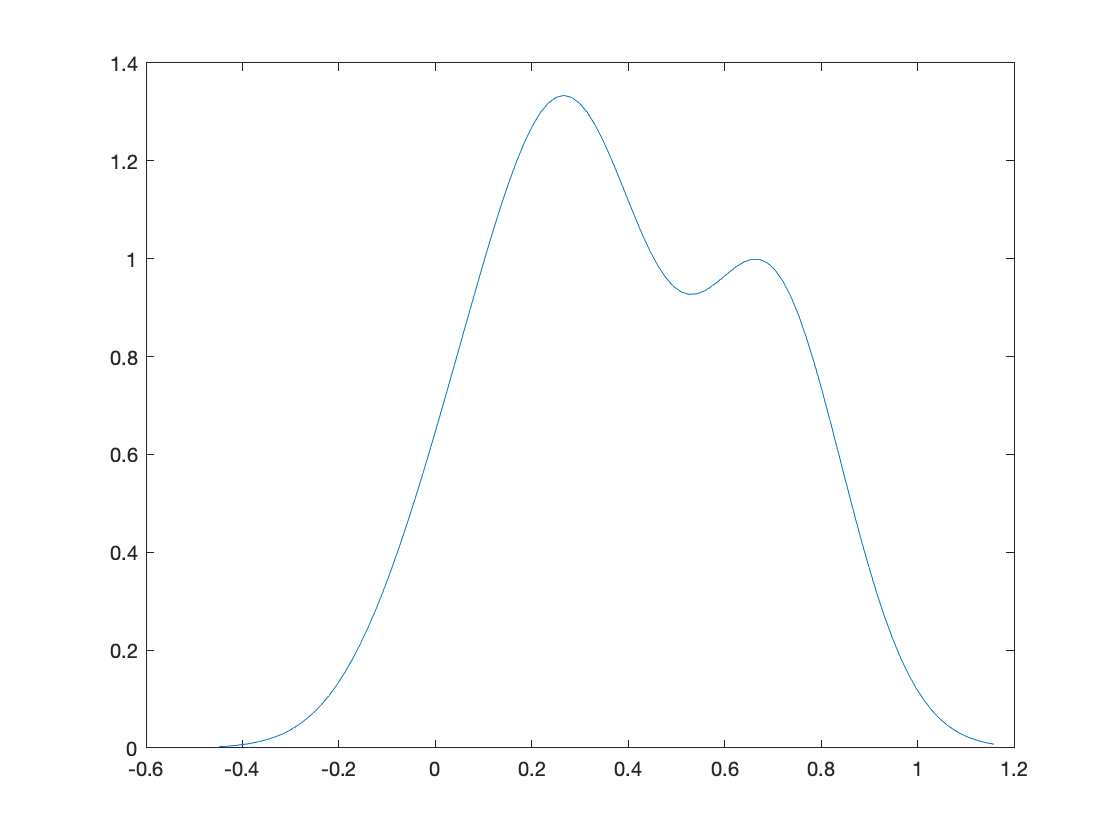

[f,yi] = ksdensity(y);
plot(yi,f)


sum(y<0)

ans = 0

sum(y>1)

ans = 0

We'll select knots based on the graphic, although more principled methods exist.

knots = [0.0, 0.1, 0.21, 0.41, 0.6, 0.81, 1];
bspline_degree = 3;
parameter_dim = length(knots)-(bspline_degree+1)

parameter_dim = 3


indices = 1:(bspline_degree+2);
pp = bspline(knots(indices));
bsplines = pp.coefs

bsplines =   116.1440         0         0         0
 -235.7621   34.8432    3.4843    0.1161
   97.2382  -42.9583    2.5917    0.6072
  -26.9906   15.3846   -2.9231    0.1851



for i=2:(length(knots)-(bspline_degree+2)+1)
    indices = (i):(i+(bspline_degree+2)-1);
    pp = bspline(knots(indices));
    bsplines= vertcat(bsplines, pp.coefs);
end


% Arbitrarily choosing the starting value, with dimension parameter_dim:
data = y;
q0_temp=[.02;.03;.04];
q0 = q0_temp/integral(@(x)(logspline_density(x,knots,bsplines,q0_temp)),knots(1),knots(length(knots)))

q0 =     0.0196
    0.0294
    0.0392


nllFunc = @(x) negLog_fiducial_likelihood(knots,bsplines,x,data);
conFunc = @(x) logspline_constraint(knots,bsplines,x);

% Set parameters (that I don't quite understand)
nRuns = 1+10;
Nscale = 3;
runTime = 15; % Time per run in seconds
nTrials = 1;
doPrint = false;

samplers = struct([]);

h = 1e-100;
M = 1;
L = 1;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
%     samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end

CHMC (L = 1)...

STARTING NEXT ITERATION
STARTING NEXT ITERATION
STARTING NEXT ITERATION


1 samples: 

mean(samplerStats{1,1}.accepted)

ans = 0

Qs = samplerQs{1,1};
save("HMC_logsplineDraws.mat",'Qs');

Qs = load("HMC_logsplineDraws.mat").Qs

Qs =     0.0196    0.0196    0.0196    0.0196
    0.0294    0.0294    0.0294    0.0294
    0.0392    0.0392    0.0392    0.0392
